# Factorio Math v5

5/24/2025

The previous version of the model arose from my study of linear algebra and relied heavily on matrix notation to describe the state of the system at a single snapshot in time. This was difficult to keep organized in the code and also difficult to compute the time evolution of the system. Computing the time evolution of the system required integrating, and I'd prefer to be able to directly evaluate the system state at any point in time rather than perform an integration every time. 

In this version, we'll develop the model by starting with the time evolution as the primary focus. We are looking for an equation which will tell us the quantity of each resource at any point in time (the "state vector"). This state vector will be the sum of multiple "actions". 


$${\bf x}(t)={\bf a}_1(t)+{\bf a}_2(t)+\dots+{\bf a}_n(t)$$


Each action vector function ${\bf a}_i(t)$ is to represent the resources over time produced/consumed by a single action (such as placing a machine or hand crafting an item). The general form of the action will be the process rates vector multiplied by a ramp function (notated with Macaulay Brackets) to turn it on/off.


$${\bf a}_i(t)={\bf p}_ic_i\left(\langle t - t_{i1}\rangle - \langle t - t_{i2}\rangle\right)$$


where ${\bf p}_i$ is the resource *rates* vector for some process, $c_i$ is the crafting speed for the machine running the process (1 for hand crafting), $t_{i1}$ is the time that the action starts, and $t_{i2}$ is when the action stops. For hand crafting, $t_{i2} - t_{i1}$ is the process/recipe duration. For placing a machine which stays permanently, $t_{i2} = \infty$.

I'll illustrate this basic shape of the function in MATLAB.

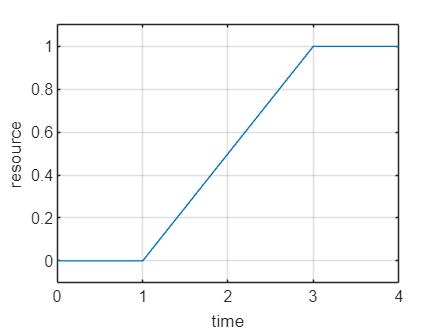

clear all; close all; clc;

t1 = 1;
t2 = 3;
p = 0.5;
c = 1;
ramp = @(t) t.*(t>zeros(size(t)));
a = @(t) p*c*(ramp(t-t1) - ramp(t-t2));

figure();
fplot(a,[0 4]);
ylim([-.1 1.1]);
grid on;
%xline(t1); xline(t2);
xlabel("time"); ylabel("resource");

Now I'll show how two actions can be overlapped.

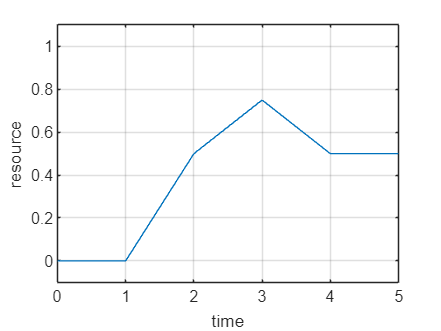

clear all; close all; clc;
ramp = @(t) t.*(t>zeros(size(t)));

% Action 1
a1 = struct();
a1.t1 = 1;
a1.t2 = 3;
a1.p = 0.5;
a1.c = 1;
a1.func = @(t) a1.p*a1.c*(ramp(t-a1.t1) - ramp(t-a1.t2));

% Action 2
a2 = struct();
a2.t1 = 2;
a2.t2 = 4;
a2.p = -0.5;
a2.c = 0.5;
a2.func = @(t) a2.p*a2.c*(ramp(t-a2.t1) - ramp(t-a2.t2));

x = @(t) a1.func(t) + a2.func(t);

figure();
fplot(x,[0 5]);
ylim([-.1 1.1]);
grid on;
%xline(a1.t1); xline(a1.t2);
%xline(a2.t1); xline(a2.t2);
xlabel("time"); ylabel("resource");

Finally, I'll show two actions but instead of just a single resource I'll use the vector for the processes to represent how multiple resources change together. 

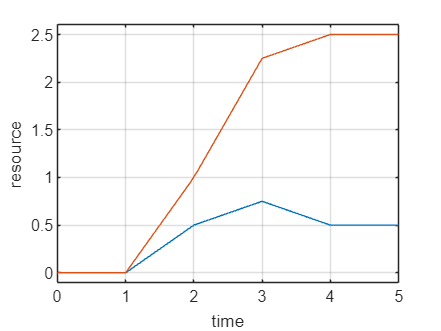

clear all; close all; clc;
ramp = @(t) t.*(t>zeros(size(t)));

% Action 1
a1 = struct();
a1.t1 = 1;
a1.t2 = 3;
a1.p = [0.5 1]; % Process vector
a1.c = 1;
a1.func = @(t) a1.p.*a1.c.*(ramp(t-a1.t1) - ramp(t-a1.t2));

% Action 2
a2 = struct();
a2.t1 = 2;
a2.t2 = 4;
a2.p = [-0.5 .5]; % Process vector
a2.c = 0.5;
a2.func = @(t) a2.p.*a2.c.*(ramp(t-a2.t1) - ramp(t-a2.t2));

x = @(t) a1.func(t) + a2.func(t);

figure();
fplot(x,[0 5]);
ylim([-.1 2.6]);
grid on;
%xline(a1.t1); xline(a1.t2);
%xline(a2.t1); xline(a2.t2);
xlabel("time"); ylabel("resource");

Now let's model a system more representative of the game. Consider the early stage of the game where we need to hand-mine some stone to make a stone furnace. Once we've done that, we can mine some coal and iron and smelt iron plates. 

There are 5 actions:

- Hand-mining stone

- Hand-crafting stone furnace

- Hand-mining coal

- Hand-mining iron

- Placing the iron-smelting stone furnace

Note that the 5th action occurs while the 4 action is still happening, to demonstrate how simultaneous actions can occur. Also note that energy consumption is calculated and the cost to place the furnace is calculated.

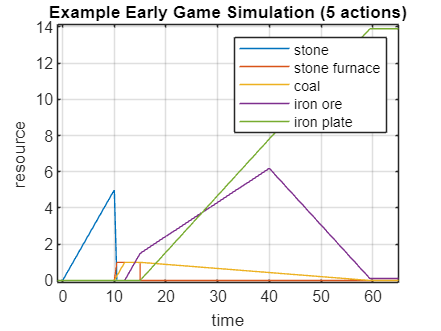

clear all; close all; clc;
ramp = @(t) t.*(t>zeros(size(t)));
step = @(t) 1.*(t>zeros(size(t)));

%% Resource Unit Vectors
stone =         [1 0 0 0 0];
stone_furnace = [0 1 0 0 0];
coal =          [0 0 1 0 0];
iron_ore =      [0 0 0 1 0];
iron_plate =    [0 0 0 0 1];

%% Processes
proc_mining_stone = struct();
proc_mining_stone.unit_rates = 1*stone;
proc_mining_stone.duration = 1;
proc_mining_stone.rates = proc_mining_stone.unit_rates / proc_mining_stone.duration; 

proc_mining_coal = struct();
proc_mining_coal.unit_rates = 1*coal;
proc_mining_coal.duration = 1;
proc_mining_coal.rates = proc_mining_coal.unit_rates / proc_mining_coal.duration; 

proc_mining_iron = struct();
proc_mining_iron.unit_rates = 1*iron_ore;
proc_mining_iron.duration = 1;
proc_mining_iron.rates = proc_mining_iron.unit_rates / proc_mining_iron.duration; 

proc_crafting_stone_furnace = struct();
proc_crafting_stone_furnace.unit_rates = 1*stone_furnace - 5*stone;
proc_crafting_stone_furnace.duration = 0.5;
proc_crafting_stone_furnace.rates = proc_crafting_stone_furnace.unit_rates / proc_crafting_stone_furnace.duration; 

proc_smelting_iron_plate = struct();
proc_smelting_iron_plate.unit_rates = 1*iron_plate - 1*iron_ore;
proc_smelting_iron_plate.duration = 3.2;
proc_smelting_iron_plate.rates = proc_smelting_iron_plate.unit_rates / proc_smelting_iron_plate.duration; 

% 1 coal contains 4 MJ of energy for burners.
% 1 Watt = 1 Joule/second.
energy_coal_burner = -(1/(4e6))*coal;

power_stone_furnace = 90e3; % 90 kW

%% Crafting speeds
c_player_default_mining_speed = 0.5;
c_player_default_crafting_speed = 1.0;
c_stone_furnace = 1.0;


%% Actions
% Action 1 - Hand-mining stone
a1 = struct();
a1.p = proc_mining_stone;
a1.c = c_player_default_mining_speed;
a1.t1 = 0;
a1.t2 = a1.t1 + 5*(a1.p.duration/a1.c);
a1.func = @(t) a1.p.rates.*a1.c.*(ramp(t-a1.t1) - ramp(t-a1.t2));

% Action 2 - Hand-crafting Stone Furnace
a2 = struct();
a2.p = proc_crafting_stone_furnace;
a2.c = c_player_default_crafting_speed;
a2.t1 = 10;
a2.t2 = a2.t1 + 1*(a2.p.duration/a2.c);
a2.func = @(t) a2.p.rates.*a2.c.*(ramp(t-a2.t1) - ramp(t-a2.t2));

% Action 3 - Hand-mining coal
a3 = struct();
a3.p = proc_mining_coal;
a3.c = c_player_default_mining_speed;
a3.t1 = 10;
a3.t2 = a3.t1 + 1*(a3.p.duration/a3.c);
a3.func = @(t) a3.p.rates.*a3.c.*(ramp(t-a3.t1) - ramp(t-a3.t2));

% Action 4 - Hand-mining iron
a4 = struct();
a4.p = proc_mining_iron;
a4.c = c_player_default_mining_speed;
a4.t1 = 12;
a4.t2 = a4.t1 + 14*(a4.p.duration/a4.c);
a4.func = @(t) a4.p.rates.*a4.c.*(ramp(t-a4.t1) - ramp(t-a4.t2));

% Action 5 - Smelting Iron Plates with Stone Furnace
a5 = struct();
a5.p = proc_smelting_iron_plate;
a5.c = c_stone_furnace;
a5.energy_rates = energy_coal_burner * power_stone_furnace; % 90 kW of energy from coal burning
a5.t1 = 15;
a5.t2 = 15 + 44.4444;  % Time to burn 1 coal
a5.cost = @(t) -step(t-a5.t1)*stone_furnace;
a5.func = @(t) (a5.energy_rates + a5.p.rates.*a5.c).*(ramp(t-a5.t1) - ramp(t-a5.t2)) + a5.cost(t);

% State Function - Sum of all actions
x = @(t) a1.func(t) + a2.func(t) + a3.func(t) + a4.func(t) + a5.func(t);

figure();
fplot(x,[-1,65]);
ylim([-.1 14.1]);
grid on;
xlabel("time"); ylabel("resource");
legend(["stone","stone furnace","coal","iron ore","iron plate"]);
title("Example Early Game Simulation (5 actions)");

In the last section we wrote out all the code explicitly. The following code will be a refactor of the previous code.

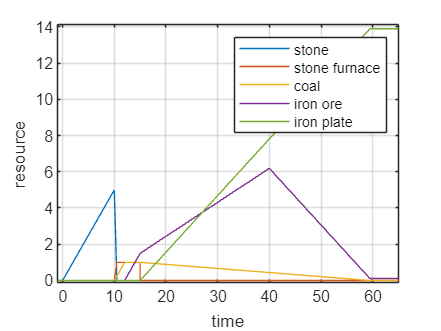

clear all; close all; clc;

% Action 1 - Hand-mining stone
a1 = action.hand_action(process.mining_stone, ...
    machine.hand_mining, ...
    0, ...
    5);
% Action 2 - Hand-crafting Stone Furnace
a2 = action.hand_action(process.crafting_stone_furnace, ...
    machine.hand_crafting, ...
    10, ...
    1);
% Action 3 - Hand-mining coal
a3 = action.hand_action(process.mining_coal, ...
    machine.hand_mining, ...
    10, ...
    1);
% Action 4 - Hand-mining iron
a4 = action.hand_action(process.mining_iron, ...
    machine.hand_mining, ...
    12, ...
    14);
% Action 5 - Smelting Iron Plates with Stone Furnace
a5 = action(process.smelting_iron_plate, ...
    resource.stone_furnace.u, ...
    machine.stone_furnace, ...
    15, ...
    15+44.4444);

a = [a1 a2 a3 a4 a5];

x = @(t) action_sum(a,t);

figure();
fplot(x,[-1,65]);
ylim([-.1 14.1]);
grid on;
xlabel("time"); ylabel("resource");
legend(["stone","stone furnace","coal","iron ore","iron plate"]);

function Sum = action_sum(a,t)
    Sum = a(1).state_func(t);
    for i=2:length(a)
        Sum = Sum + a(i).state_func(t);
    end
end